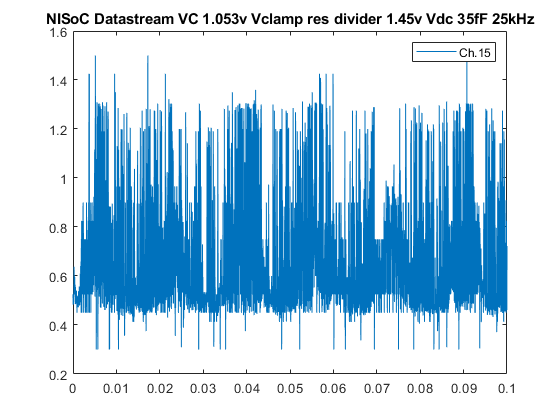

%NISoC Load, Parse, and Plot

filename1 = ['plots/20210728-191614_QFP8_NeuroCube_lab_pluggedin_35fF_BW111_voltage_clamp_vref_1.053v_res_divider_vin_dc_1.55v_Ch15.csv'];
dt1 = dlmread(filename1,',',0,0);
data{1}.data    = (dt1(1,:) * 1.2/4095)+0.3;                 % convert decimal to volts
%data{1}.rst     = dt1(2,:);
%data{1}.cds     = dt1(3,:);

gain            = 1;
CDS_mode        = false;
VC_mode         = true;
data{1}.fs      = 25000;                          % set sampling frequency 
data{1}.time    = 0:1/data{1}.fs:(length(data{1}.data)-1)*1/data{1}.fs; 

figure(1);
h = plot(data{1}.time,data{1}.data);
title('NISoC Datastream VC 1.053v Vclamp res divider 1.45v Vdc 35fF 25kHz');
xlim([0 0.1])
legend('Ch.15')

## Spilt Datastream to Sig_{int1} and Sig_{int2}

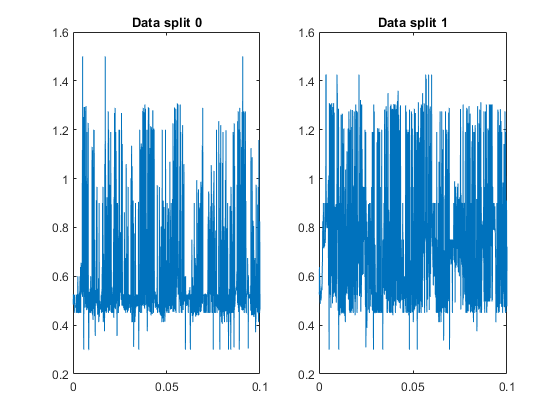

if VC_mode
    % the data set with rst experienced rstota pulse just before 
    data{2}.data    = data{1}.data(2:2:end);      % should be the real data
    data{2}.time    = data{1}.time(2:2:end);
    data{2}.fs      = round(data{1}.fs/2);
    data{3}.data    = data{1}.data(1:2:end);     % should be reference data
    data{3}.time    = data{1}.time(1:2:end);
    data{3}.fs      = round(data{1}.fs/2);
    
    figure(2); subplot(1,2,1);
    plot(data{2}.time,data{2}.data);
    title('Data split 0');
    %ylim([0.594 0.602])
    xlim([0 0.1]);
    subplot(1,2,2);
    plot(data{3}.time,data{3}.data);
    title('Data split 1');
    xlim([0 0.1]);
    %ylim([0.594 0.602])
end

**Design a low pass filter**

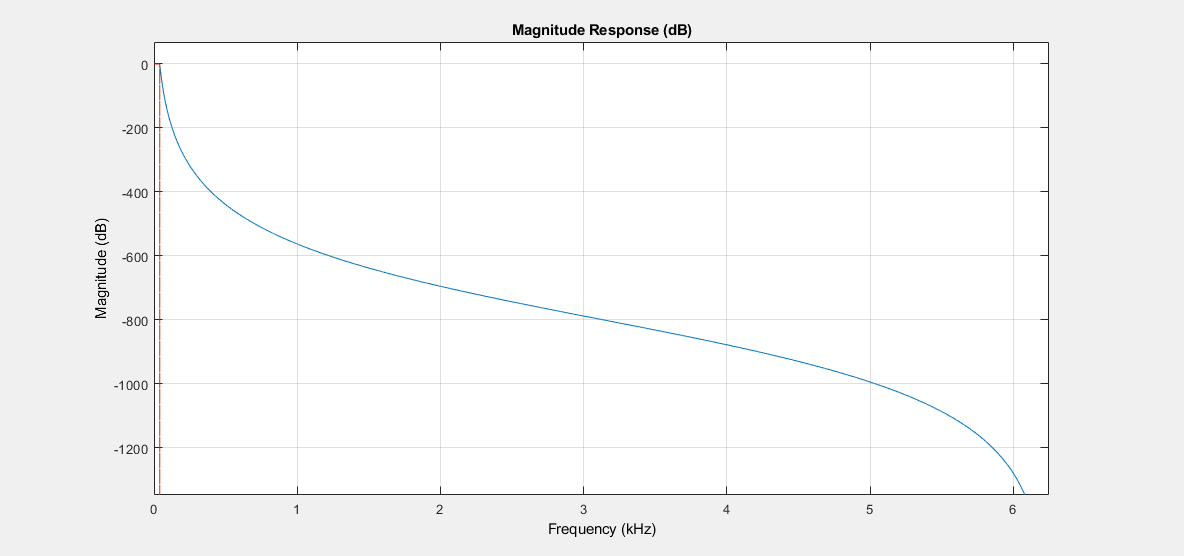

%lpFilt = designfilt('lowpassfir', ...
%                    'FilterOrder', 30, ...
%                    'CutoffFrequency', 58, ... 
%                    'SampleRate', 12500);
lpFilt = designfilt('lowpassiir', ... 
                    'FilterOrder', 20, ... 
                    'HalfPowerFrequency', 40, ...
                    'SampleRate', 12500);
fvtool(lpFilt)

**Design a bandstop filter**

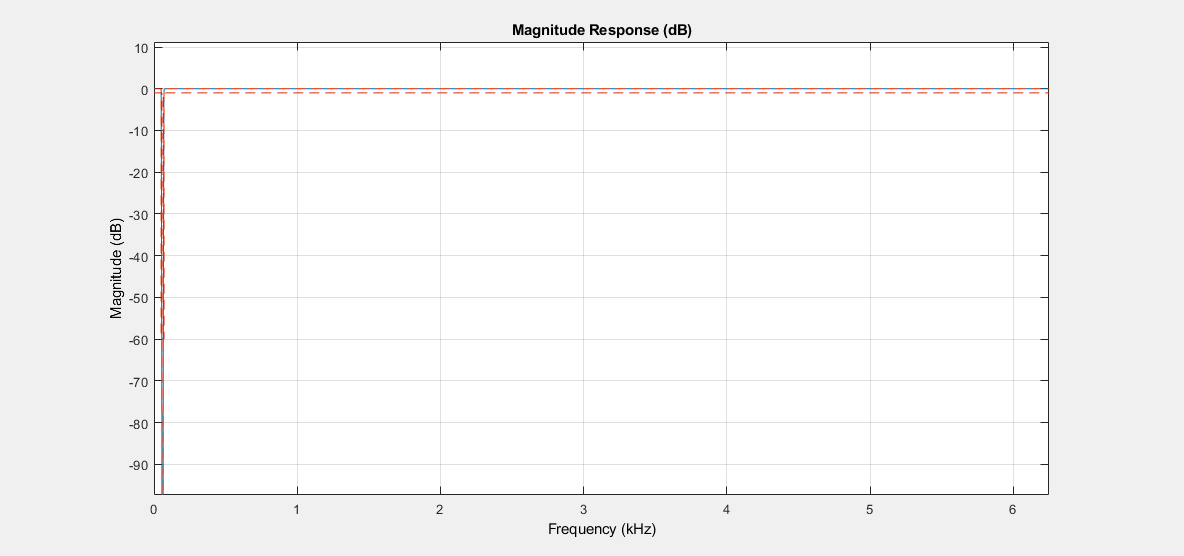

%lpFilt = designfilt('lowpassfir', ...
%                    'FilterOrder', 30, ...
%                    'CutoffFrequency', 58, ... 
%                    'SampleRate', 12500);
sbFilt = designfilt('bandstopiir', ... 
                    'StopbandAttenuation', 60, ... 
                    'PassbandRipple2', 1, ...
                    'PassbandFrequency2', 70, ...
                    'StopbandFrequency2',65, ...
                    'PassbandRipple1', 1, ...
                    'StopbandFrequency1', 55,...
                    'PassbandFrequency1', 50, ...
                    'SampleRate', 12500);
fvtool(sbFilt)

## Calculate the Integrated Current


$$I = \Delta V * \frac{C}{\Delta t}$$


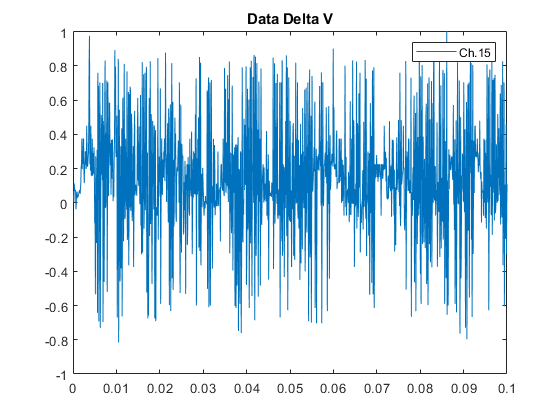

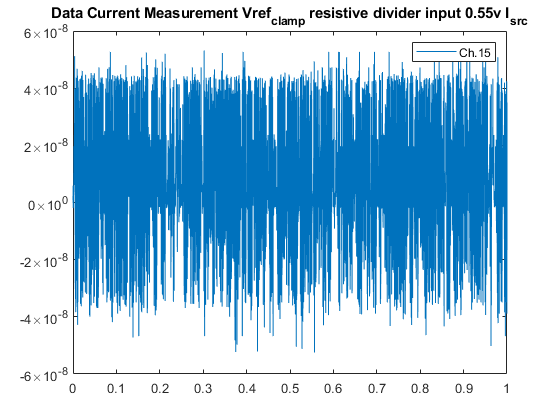

Current Measurement Average: 6.1771e-09


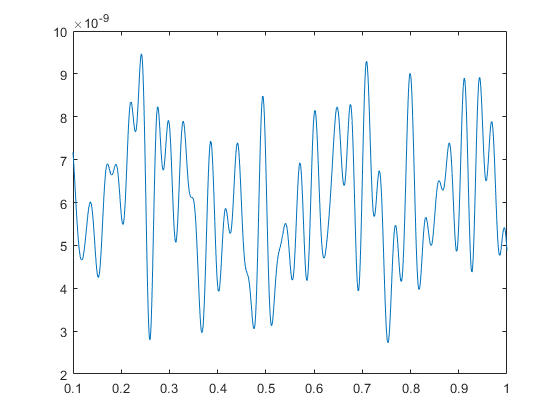

Current Measurement Average LPfilt: 6.0173e-09


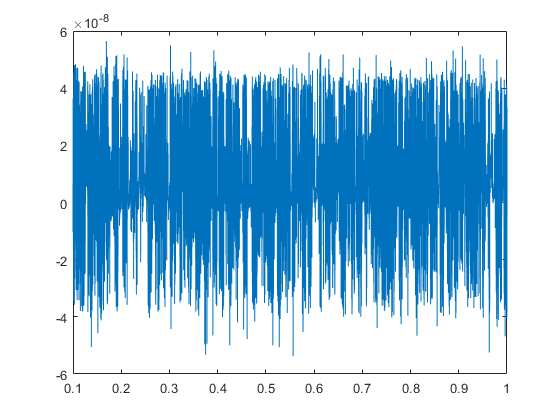

Current Measurement Average SBfilt: 6.0278e-09


C       = 2.1e-12;
deltaT  = 1/data{1}.fs;

if VC_mode
    data{4}.data = zeros(length(data{2}.data),1);
    
    for i = 1:length(data{2}.data)                         % iterate through datastream
        data{4}.data(i) = (data{3}.data(i)-data{2}.data(i));% create delta V set
    end
    
    data{4}.fs      = data{2}.fs;                         % adjust sampling rate 
    data{4}.time    = data{2}.time;                       % use the sample set time for corrected set                              
    
    data{5}.data = data{4}.data .* C/deltaT;
    data{5}.time = data{4}.time;
    data{5}.fs   = data{4}.fs;   
    
    figure(20);
    h = plot(data{4}.time,data{4}.data);
    title('Data Delta V');
    ax = ancestor(h, 'axes');
    ax.YAxis.Exponent = 0;
    xlim([0 0.1]);
  legend('Ch.15');
    
    figure(81);
    h = plot(data{5}.time, data{5}.data);
    title('Data Current Measurement Vref_{clamp} resistive divider input 0.55v I_{src}');
    ax = ancestor(h, 'axes');
    ax.YAxis.Exponent = 0;
    xlim([0 1]);
    
    legend('Ch.15');
    
    disp(['Current Measurement Average: ',num2str(mean(data{5}.data))]);
    
    % low pass filtering data (60Hz cutoff) and plotting filtered data from 0.1 to 1sec    
    data{6}.data = filtfilt(lpFilt, data{5}.data);
    data{6}.time = data{5}.time;
    data{6}.fs   = data{5}.fs;
    
    rngoi = 0.1<data{5}.time & data{5}.time<1.0;  % range of interest, considering filter effects at t = 0
    figure(22); 
    title('Data Filtered Current Measurement 941 mV_{clamp} 0.2 nA I_{src}');
    plot(data{6}.time(rngoi), data{6}.data(rngoi));

    disp(['Current Measurement Average LPfilt: ',num2str(mean(data{6}.data(rngoi)))]);
    
    % Stopband filtering data (60Hz) and plotting filtered data from 0.1 to 1sec    
    data{7}.data = filtfilt(sbFilt, data{5}.data);
    data{7}.time = data{5}.time;
    data{7}.fs   = data{5}.fs;
    
    rngoi = 0.1<data{5}.time & data{5}.time<1.0;  % range of interest, considering filter effects at t = 0
    figure(23); 
    title('Data Filtered Current Measurement 941 mV_{clamp} 0.2 nA I_{src}');
    plot(data{7}.time(rngoi), data{7}.data(rngoi));

    disp(['Current Measurement Average SBfilt: ',num2str(mean(data{7}.data(rngoi)))]);
end

## PSD (periodogram) 

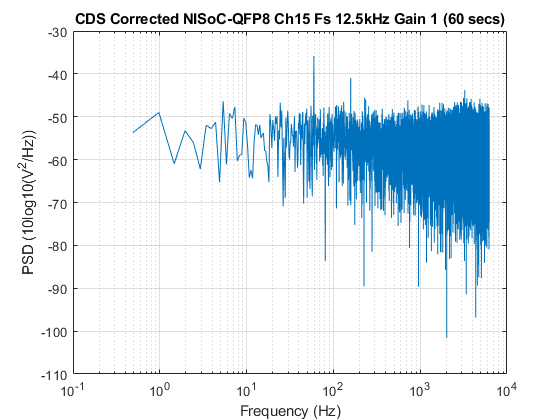

[dPD, f, Vnrms] = psd_rms(data{4}.data, data{4}.fs,gain,1, 2);
faidx = find(f(f<1));
if (length(faidx) == 0)
    faidx = 1;
else
    faidx = faidx(1);
end
fzidx = find(f(f<12500));
fzidx = fzidx(end);
[dPD, f, Vnrms] = psd_rms(data{4}.data, data{4}.fs,gain,faidx, fzidx);

figure(29);
%hold on
plot(f, 10*log10(dPD));
grid on
title(['CDS Corrected NISoC-QFP8 Ch15 Fs 12.5kHz Gain ',num2str(gain),' (60 secs)']); 
xlabel('Frequency (Hz)');
ylabel('PSD (10log10(V^{2}/Hz))');
set(gca, 'XScale', 'log') 
hold off


% Noise calculation presented in uVrms
disp(['Vrms calculation: ',num2str(Vnrms)]);

Vrms calculation: 0.14323


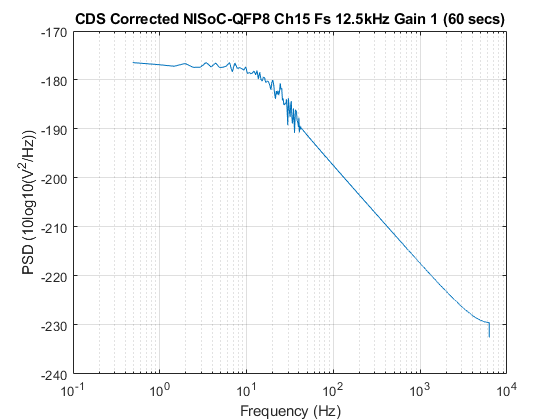


[dPD, f, Vnrms] = psd_rms(data{6}.data, data{6}.fs,gain,1, 2);
faidx = find(f(f<1));
if (length(faidx) == 0)
    faidx = 1;
else
    faidx = faidx(1);
end
fzidx = find(f(f<12500));
fzidx = fzidx(end);
[dPD, f, Vnrms] = psd_rms(data{6}.data, data{6}.fs,gain,faidx, fzidx);

figure(30);
%hold on
plot(f, 10*log10(dPD));
grid on
title(['CDS Corrected NISoC-QFP8 Ch15 Fs 12.5kHz Gain ',num2str(gain),' (60 secs)']); 
xlabel('Frequency (Hz)');
ylabel('PSD (10log10(V^{2}/Hz))');
set(gca, 'XScale', 'log') 
%xlim([0 100]);
hold off


% Noise calculation presented in uVrms
disp(['Vrms calculation: ',num2str(Vnrms)]);

Vrms calculation: 6.4531e-09


[dPD, f, Vnrms1] = psd_rms(data{3}.data, data{3}.fs,gain,3, 122);
[dPD, f, Vnrms2] = psd_rms(data{3}.data, data{3}.fs,gain,126, 12801);
Vnrmstot = Vnrms1 + Vnrms2;
disp(Vnrmstot)

    0.1190



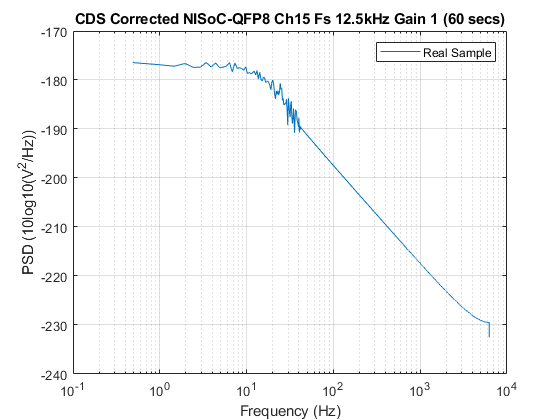

rownames = {'Real Sample','Ref Sample','Corrected'};
legend(rownames)

Over a 12.5kHz BW, the rms noise for each data set are as follows:

% table
Vrms_vals = [0.0042;0.0041;0.0045];
table(Vrms_vals,'RowNames',rownames')

ans = 3×1 table
                   Vrms_vals
                   _________

    Real Sample     0.0042  
    Ref Sample      0.0041  
    Corrected       0.0045  


## Save Data of choice to CSV

%writematrix(cds_data,'CDS_subtracted_NISoC_QFP4_ch0_shorted_input_vref_CDS_gain_60secs.csv')


## PSD RMS Function

function [dPD, f, Vnrms] = psd_rms(data,Fs,gain,faidx,fzidx)
    N = length(data);
    dFT = fft(data);       % fft
    dFT = dFT(1:N/2+1);     % DC to Nyquist 
    dFT = dFT/gain;
    dPD = (1/(Fs*N)) * abs(dFT).^2;  % periodogram
    dPD(2:end-1) = 2*dPD(2:end-1);      % factor of 2 to conserve power
    f = 0:Fs/N:Fs/2;
    
    % Noise calculation presented in uVrms
    f(fzidx);
    df = f(fzidx) - f(fzidx-1);
    BW = faidx:fzidx; 
    Vnrms = sqrt(sum(dPD(BW)*(df)));   
end